# **Lubrication Project**

## Setup

Code initiation

clc
clear
close all

set(0,'DefaultFigureWindowStyle','docked')

## Problem Statement

Consider an extrusion process where a fluid of high viscosity is squeezed between a flat solid surface and a roller of radius 𝑎 as shown in the figure. The roller is rotating at an angular velocity $\omega$, reducing the thickness of the fluid layer from $h_1
$ to $h_2

$ with a minimum gap of $\varepsilon$ between the roller and the flat boundary.

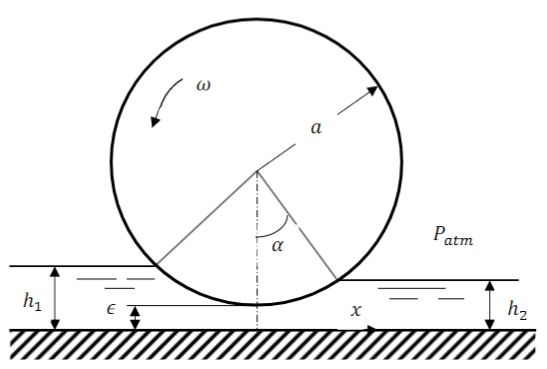

Assume a profile for the liquid layer between the roller and the flat surface in the form:

## 
$$h(x) = \varepsilon + a(1-\cos(\alpha))$$


and assume 𝛼 is small.

## a. Use the lubrication approximation to determine the pressure distribution in the liquid film and show it graphically.

syms mu dpdx h y V alpha h1 h2 a Q x y e w
h = e + a*(1 - (x/a))

$$h = e-a\,\left(\frac{x}{a}-1\right)$$

alpha = x / a

$$alpha = \frac{x}{a}$$

c1 = ( a*w - ( 1/(2*mu) * dpdx * (e^2) ) ) / e

$$c1 = \frac{a\,w-\frac{\mathrm{dpdx}\,e^{2}}{2\,\mu }}{e}$$

u = ( 1/(2*mu) * dpdx * (h^2) ) + (c1 * h)

$$u = \frac{\mathrm{dpdx}\,{\left(e-a\,\left(\frac{x}{a}-1\right)\right)}^{2}}{2\,\mu }+\frac{\left(e-a\,\left(\frac{x}{a}-1\right)\right)\,\left(a\,w-\frac{\mathrm{dpdx}\,e^{2}}{2\,\mu }\right)}{e}$$

Find Q:

fq = Q == int(u, y, [0 h])

$$fq = Q=\frac{\left(a\,\mathrm{dpdx}\,e-\mathrm{dpdx}\,e\,x+2\,a\,\mu \,w\right)\,{\left(a+e-x\right)}^{2}}{2\,e\,\mu }$$

dpdx = rhs(isolate(fq, dpdx))

$$dpdx = \frac{2\,e\,\mu \,\left(Q-\frac{a\,w\,{\left(a+e-x\right)}^{2}}{e}\right)}{\left(a\,e-e\,x\right)\,{\left(a+e-x\right)}^{2}}$$

b1 = sqrt(a^2 - (a-h1)^2)

$$b1 = \sqrt{a^{2}-{\left(a-h_{1}\right)}^{2}}$$

b2 = a*alpha

$$b2 = x$$

int(dpdx, x, [-b1 b2])

$$ans = \int_{-\sqrt{a^{2}-{\left(a-h_{1}\right)}^{2}}}^{x}\frac{2\,e\,\mu \,\left(Q-\frac{a\,w\,{\left(a+e-x\right)}^{2}}{e}\right)}{\left(a\,e-e\,x\right)\,{\left(a+e-x\right)}^{2}}\mathrm{d}x$$

## b. Determine the maximum angular velocity which can be used to avoid cavitation.

## c. Calculate the lubrication thickness and the maximum angular velocity for the following conditions*:

#### $a = 1m$, $h_1 = 20mm$, $h_2 = 2mm$, $\varepsilon = 1mm$, $\mu = 10^4 \times \mu_{water}$